# Getting Started with <Linking Number>

## Description

A C++ class with MATLAB interface for the computation of the linking number.

## MATLAB interface

Matlab usage is very easy, there is a unique command *lk* with a variable number of arguments* lk(p1,p2,...,pn)* where pk is a n x 3  matrix storing the points of the piecewise linear curve.

## Example

Build two non intersecting (topological) circles traveled 3 times

clear all;

npts = 20;

theta = [2*pi*linspace(0,1,npts)]';
x     = 2.5*cos(3*theta);
y     = 2.5*sin(3*theta);
z     = zeros(size(theta));
P     = [ x'; y'; z' ];

xx = z;
yy = x+1;
zz = y;
Q    = [ xx'; yy'; zz' ];

Now P and Q contains the list of point, daw it:

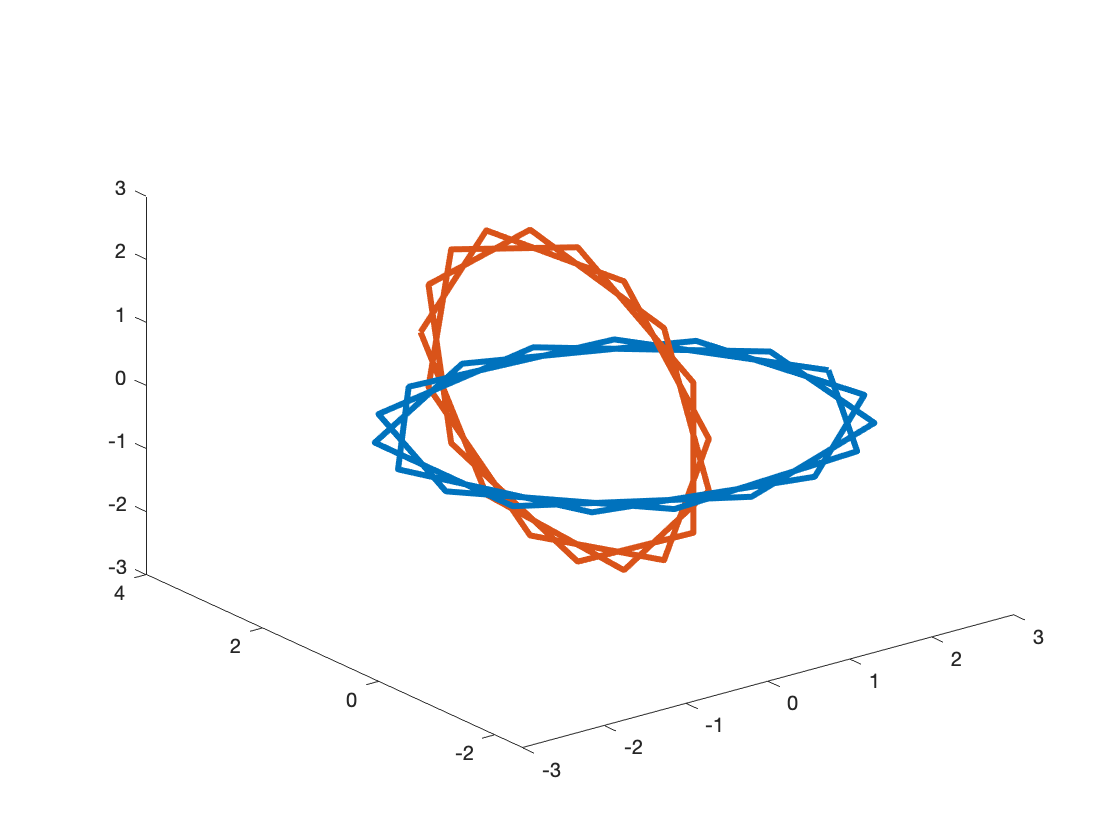

plot3( x, y, z, xx, yy, zz, 'LineWidth', 3 );

Now compute linking number (expected +9 or -9).

[L,E] = lk( P, Q )

L = 2×2 int64 matrix
    0   -9
   -9    0


E = 	1.0e+-12 *

                   0   0.632379590154903
   0.632379590154903                   0


  
fprintf('L = %d, err = %g\n', L(1,2), E(1,2) ) ;

L = -9, err = 6.3238e-13
